# MPC Distrubance Rejection

## System

mcart = 0.493;
mpend = 0.312;
Ipend = 0.00024;
l = 0.04;
f = 0.01;
kt = 0.11;
R = 10;
r = 0.0335;
g = 9.81;
inputGain = 2*kt/(R*r);

%% State Space
A = [0 1 0 0;
    0 (-(Ipend + mpend*l^2)*f)/(Ipend*(mcart+mpend)+ mcart*mpend*l^2) mpend^2*g*l^2/(Ipend*(mcart+mpend)+ mcart*mpend*l^2) 0;
    0 0 0 1;
    0 -mpend*l*f/(Ipend*(mcart+mpend)+ mcart*mpend*l^2) mpend*g*l*(mcart+mpend)/(Ipend*(mcart+mpend)+ mcart*mpend*l^2) 0];
B = [0; (Ipend+mpend*l^2)/(Ipend*(mcart+mpend)+ mcart*mpend*l^2);
    0; mpend*l/(Ipend*(mcart+mpend)+ mcart*mpend*l^2)];

## LQR

lqr_weight = [100 1 1e6 1e2];
Q_lqr = diag(lqr_weight);
R_lqr = 1;
C= [1 0 0 0];
D = 0;
K=lqr(A,B,Q_lqr,R_lqr);

## Closed Loop System

A_cl=A-B*K;
B_cl=B;
plant=ss(A_cl,B_cl,C,D);
PP = c2d(plant,0.2,'zoh');
A=PP.A;
B=PP.B;
C=PP.C;

## Augmented State Space 

state_n = size(A, 1);

A_new = [A zeros(state_n,1); C 1];
B_new = [B; 0];
C_new = [C 0; zeros(1,state_n) 1];
W_new = [zeros(state_n, 1); -1];

input_n = size(B_new, 2);

## MPC Formulation

N = 2;
R = 1; % Control penalty
Q = diag([2e4; 1e4]);  % output = [position; integral of error]
Qbar = blkdiag(Q,Q);
Rbar = blkdiag(R,R);

Tbar = [C_new*A_new;C_new*A_new^2];
Sbar = [C_new*B_new zeros(2,1);C_new*A_new*B_new C_new*B_new];
Wbar = [C_new*W_new;C_new*W_new + C_new*A_new*W_new];
H = (Rbar+Sbar'*Qbar*Sbar);
H = (H+H')/2;

G = [tril(eye(N*input_n));-tril(eye(N*input_n))];
S = zeros(2*N*input_n,5);
W = 12*ones(2*N,1);

iter = 2000;
%r = ones(iter,1);
r = square([1:iter+N+1]/200);

Xact = [];
Uopt = [];
X = [0;0;0;0;0];
U = 0;

U_disturb = 0;
X_disturb = [0; 0; 0; 0; 0];

warning('off','all')
options = optimoptions('quadprog');
options.Display = 'none';

% Simulation
for ii = 1:iter-1
    Xact(:,ii) = X;
    Rbarref = [r(ii);0;r(ii);0];
    
    f = 2*(X'*Tbar'*Qbar*Sbar - Rbarref'*Qbar*Sbar - r(ii)*Wbar'*Qbar*Sbar); 
    
    Z = quadprog(H,f,G,W+S*X,[],[],[],[],[],options);
    if(mod(ii,200) == 0)
        Z
    end
    
    Uopt(ii) = Z(1) + U_disturb;
    U = Uopt(ii);

    X = A_new*X + B_new*U + W_new*r(ii) + X_disturb;
end

Z =    -9.7038
    0.0688


Z =   -10.0196
   -0.0211


Z =    -9.9989
   -0.0169


Z =     7.8290
   -0.3997


Z =    10.0999
    0.0229


Z =     9.9964
    0.0170


Z =   -12.0000
    0.8630


Z =    -9.8474
   -0.0085


Z =   -10.0054
   -0.0171


## Plotting

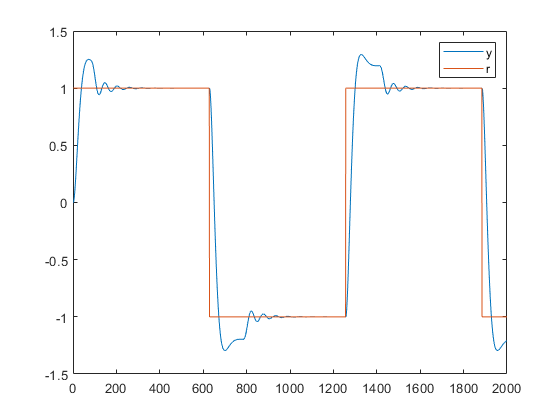

Xact(:,ii+1) = X;

%% Plotting
y=C_new*Xact;
plot([1:iter],y(1,1:iter),[1:iter],r(1:iter))
legend('y','r')

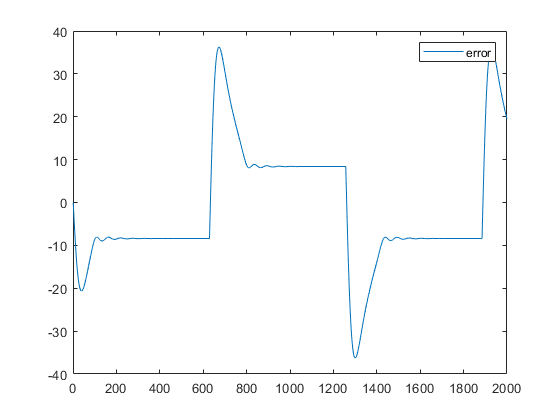

plot([1:iter],y(2,1:iter))
legend('error')

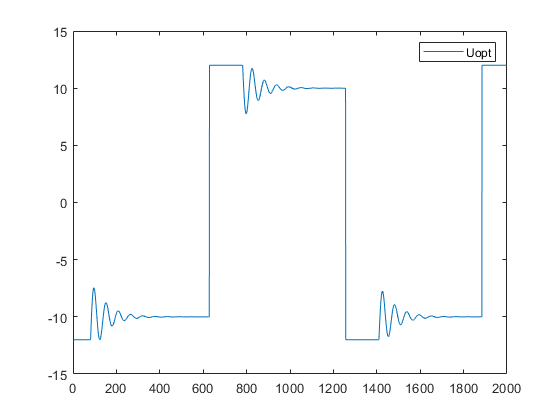

plot([1:iter-1], Uopt(1, 1:iter-1))
legend('Uopt')